# AuE-6600 | Dynamic Performance of Vehicles

## Homework 5

### Problem 1

Give limits on the Understeer Gradient, so that the characteristic velocity of a vehicle with wheelbase 3.1 m will be in the desired range of 80-120 km/h. What is maximum achievable steering sensitivity in this range (yaw velocity response)? Assuming a steering gear ratio of 19, what steering wheel angle does the driver have to provide for cornering with ay= 5 m/s2 lateral acceleration?

### Solution 1

1. Give limits on the Understeer Gradient, so that the characteristic velocity of a vehicle with wheelbase 3.1 m will be in the desired range of 80-120 km/h.

% Given data
l = 3.1; % m
v_min = 80; % km/h
v_min = v_min/3.6; % m/s
v_max = 120; % km/h
v_max = v_max/3.6; % m/s
% Calculate UG
UG_min = l/(v_max^2);
UG_max = l/(v_min^2);
fprintf("Limits on the understeer gradient are %.4f rad-s^2/m and %.4f rad-s^2/m", UG_min, UG_max);

Limits on the understeer gradient are 0.0028 rad-s^2/m and 0.0063 rad-s^2/m

2. What is maximum achievable steering sensitivity in this range (yaw velocity response)?

% Calculate steering sensitivity
steer_sensitivity_min = v_min/(2*l);
steer_sensitivity_max = v_max/(2*l);
fprintf("Steering sensitivity is in the range of %.4f Hz and %.4f Hz\n" + ...
        "Maximum steering sensitivity is %.4f Hz", ...
        steer_sensitivity_min, steer_sensitivity_max, max(steer_sensitivity_min, steer_sensitivity_max));

Steering sensitivity is in the range of 3.5842 Hz and 5.3763 Hz
Maximum steering sensitivity is 5.3763 Hz

3. Assuming a steering gear ratio of 19, what steering wheel angle does the driver have to provide for cornering with ay = 5 m/s^2 lateral acceleration?

% Given data
steer_ratio = 19;
a_y = 5; % m/s^2
% Calculate turning radius
R_min = v_min^2/a_y;
R_max = v_max^2/a_y;
% Calculate steering angle
delta_min = v_min/(R_min*steer_sensitivity_min);
delta_max = v_max/(R_max*steer_sensitivity_max);
% Calculate steering wheel angle
steer_angle_min = delta_min*steer_ratio;
steer_angle_max = delta_max*steer_ratio;
fprintf("The driver have to provide steering wheel angle of %.4f rad for cornering with a_y = 5 m/s^2 at v_x = %.4f m/s\n" + ...
        "The driver have to provide steering wheel angle of %.4f rad for cornering with a_y = 5 m/s^2 at v_x = %.4f m/s\n", ...
        steer_angle_min, v_min, steer_angle_max, v_max);

The driver have to provide steering wheel angle of 1.1927 rad for cornering with a_y = 5 m/s^2 at v_x = 22.2222 m/s
The driver have to provide steering wheel angle of 0.5301 rad for cornering with a_y = 5 m/s^2 at v_x = 33.3333 m/s


### Problem 2

Consider the following Bicycle model vehicle:

- Mass: 120 slug

- Wheelbase: 9 ft.

- Weight Distribution: Defined below.

- Front Cornering Stiffness: 350 lb/deg

- Rear Cornering Stiffness: 350 lb/deg

This vehicle is being driven on a 320 ft radius (left turn) skid pad.

For the weight distributions 60% front (a=3.6 ft, b=5.4 ft), 50% front (a=4.5 ft, b=4.5 ft), and 40% front (a=5.4 ft, b=3.6 ft), answer the following:

A. Calculate the six stability derivatives for this vehicle at a speed of 30 mph.

B. Determine the stability factor.

C. Determine the critical speed. If it does not exist, say “does not exist”.

D. Determine the distance from the neutral steer point (d) to the front tire.

E. Determine the static margin.

F. Plot the theoretical vehicle stabilizing moment against velocity from 0 to 75 mph. That is, plot $N_{\beta } \cdot \beta$ + $N_r \cdot r$ vs. $v_x$. (See hint below.)

G. Plot the vehicle control moment against the vehicle stabilizing moment for velocities from 0 to 75 mph. That is, plot $N_{\delta } \cdot \delta$ vs. $N_{\beta } \cdot \beta$ + $N_r \cdot r$. (See hint below.)

You should plot the results for all three models in one figure for questions F and G.

Hint for part F:

Select a range of velocities from 0 to 75 mph in increments of, say, 1 mph. For each of these velocities you need to calculate theoretical values for $N_{\beta \;}$, $\beta$, $N_r$, and $r$. The theoretical $\beta$ can be derived as:


$$\beta =\frac{b}{R}-\frac{a*m*v^2 }{l*R*C_{\alpha R\;} }$$


Hint for part G:

Use the understeer gradient and the lateral acceleration at each velocity to find $\delta$ at each velocity.

### Solution 2

1. Calculate the six stability derivatives for this vehicle at a speed of 30 mph.

% Given data
m = 120; % slug
m = m*14.594; % kg
l = 9; % ft
l = l/3.281; % m
C_alpha_F = 350; % lb/deg
C_alpha_F = C_alpha_F*4.4482*180/pi; % N/rad
C_alpha_R = 350; % lb/deg
C_alpha_R = C_alpha_R*4.4482*180/pi; % N/rad
R = 320; % ft
R = R/3.281; % m
v_x = 30; % mph
v_x = v_x/2.237; % m/s
a = [3.6 4.5 5.4]; % ft
a = a/3.281; % m
b = [5.4 4.5 3.6]; % ft
b = b/3.281; % m
% Calculate stability derivatives
YB = ones(1,3).*(-(C_alpha_F+C_alpha_R)); % N/rad
Yr = ((b*C_alpha_R)-(a*C_alpha_F))/(v_x); % N-s/rad
Yd = ones(1,3).*(C_alpha_F); % N/rad
NB = (b*C_alpha_R)-(a*C_alpha_F); % N-m/rad
Nr = -((a.^2*C_alpha_F)+(b.^2*C_alpha_R))/(v_x); % N-m-s/rad
Nd = ones(1,3).*(a*C_alpha_F); % N-m/rad
stability_derivatives = [YB' Yr' Yd' NB' Nr' Nd'];
fprintf("The stability derivatives are printed in a tabular form below\n" + ...
        "Rows represent weight distributions: 60%% front (a=3.6 ft, b=5.4 ft), 50%% front (a=4.5 ft, b=4.5 ft), and 40%% front (a=5.4 ft, b=3.6 ft)\n" + ...
        "Columns represent stability derivatives: YB (N/rad), Yr (N-s/rad), Yd (N/rad), NB (N-m/rad), Nr (N-m-s/rad), Nd (N-m/rad)");

The stability derivatives are printed in a tabular form below
Rows represent weight distributions: 60% front (a=3.6 ft, b=5.4 ft), 50% front (a=4.5 ft, b=4.5 ft), and 40% front (a=5.4 ft, b=3.6 ft)
Columns represent stability derivatives: YB (N/rad), Yr (N-s/rad), Yd (N/rad), NB (N-m/rad), Nr (N-m-s/rad), Nd (N-m/rad)

disp(stability_derivatives);

   1.0e+05 *

   -1.7840    0.0365    0.8920    0.4894   -0.2603    0.9787
   -1.7840         0    0.8920         0   -0.2502    1.2234
   -1.7840   -0.0365    0.8920   -0.4894   -0.2603    1.4681



2. Determine the stability factor.

% Calculate UG
UG = (m*((C_alpha_R*b)-(C_alpha_F*a)))/(l*C_alpha_F*C_alpha_R);
% Calculate stability factor
K = UG/l; % rad-s^2/m^2
fprintf("The stability factors are printed in a vector form below\n" + ...
        "Rows represent weight distributions: 60%% front (a=3.6 ft, b=5.4 ft), 50%% front (a=4.5 ft, b=4.5 ft), and 40%% front (a=5.4 ft, b=3.6 ft)\n" + ...
        "Column represents stability factor: K (rad-s^2/m^2)");

The stability factors are printed in a vector form below
Rows represent weight distributions: 60% front (a=3.6 ft, b=5.4 ft), 50% front (a=4.5 ft, b=4.5 ft), and 40% front (a=5.4 ft, b=3.6 ft)
Column represents stability factor: K (rad-s^2/m^2)

disp(K');

    0.0014
         0
   -0.0014



3. Determine the critical speed. If it does not exist, say “does not exist”.

% Calculate critical speed
v_crit = sqrt(-1./K);
fprintf("The critical speeds are printed in a vector form below\n" + ...
        "Rows represent weight distributions: 60%% front (a=3.6 ft, b=5.4 ft), 50%% front (a=4.5 ft, b=4.5 ft), and 40%% front (a=5.4 ft, b=3.6 ft)\n" + ...
        "Column represents critical speed: v_crit (m/s)");

The critical speeds are printed in a vector form below
Rows represent weight distributions: 60% front (a=3.6 ft, b=5.4 ft), 50% front (a=4.5 ft, b=4.5 ft), and 40% front (a=5.4 ft, b=3.6 ft)
Column represents critical speed: v_crit (m/s)

for i=1:length(v_crit)
    if isreal(v_crit(i))
        disp(v_crit(i))
    else
        disp('does not exist')
    end
end

does not exist
does not exist


   26.4310



4. Determine the distance from the neutral steer point (d) to the front tire.

% Calculate neutral steer point (NSP)
NSP = C_alpha_R/(C_alpha_F+C_alpha_R);
% Calculate distance from the neutral steer point to the front tire
d = NSP*l;
fprintf("The distance from the neutral steer point to the front tire is %.4f m", d);

The distance from the neutral steer point to the front tire is 1.3715 m

5. Determine the static margin.

% Calculate static margin
SM = ((ones(1,3)*d)-a)./(ones(1,3)*l);
fprintf("The static margins are printed in a vector form below\n" + ...
        "Rows represent weight distributions: 60%% front (a=3.6 ft, b=5.4 ft), 50%% front (a=4.5 ft, b=4.5 ft), and 40%% front (a=5.4 ft, b=3.6 ft)\n" + ...
        "Column represents static margin: SM (uniless or %%)");

The static margins are printed in a vector form below
Rows represent weight distributions: 60% front (a=3.6 ft, b=5.4 ft), 50% front (a=4.5 ft, b=4.5 ft), and 40% front (a=5.4 ft, b=3.6 ft)
Column represents static margin: SM (uniless or %)

disp(SM');

    0.1000
         0
   -0.1000



6. Plot the theoretical vehicle stabilizing moment against velocity from 0 to 75 mph. That is, plot $N_{\beta } \cdot \beta$ + $N_r \cdot r$ vs. $v_x$.

Hint:

Select a range of velocities from 0 to 75 mph in increments of, say, 1 mph. For each of these velocities you need to calculate theoretical values for $N_{\beta \;}$, $\beta$, $N_r$, and $r$. The theoretical $\beta$ can be derived as:


$$\beta =\frac{b}{R}-\frac{a*m*v^2 }{l*R*C_{\alpha R\;} }$$


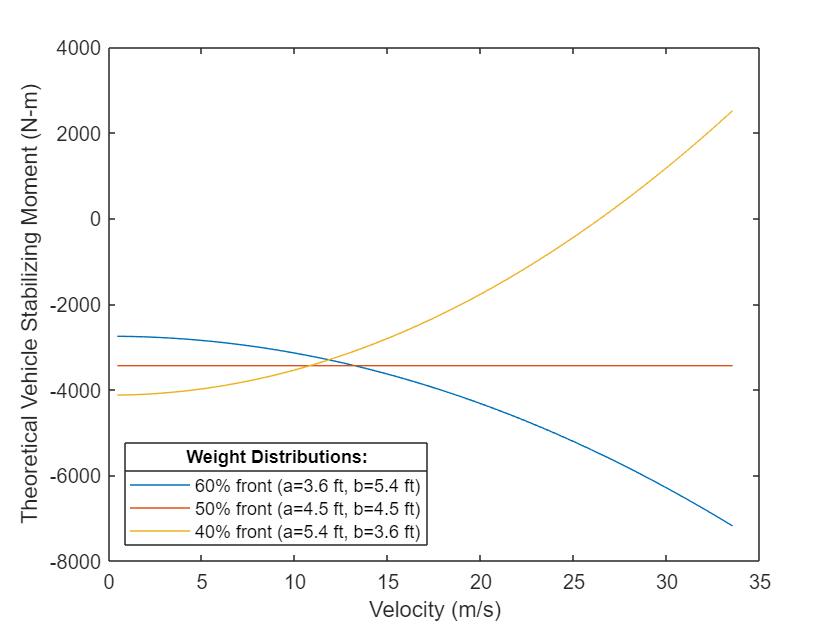

v_x = 0:75; % mph
v_x = v_x/2.237; % m/s
NB = [];
B = [];
Nr = [];
r = [];
for i=1:length(v_x)
    NB(:,i) = (b*C_alpha_R)-(a*C_alpha_F);
    B(:,i) = (b/R)-(a*m*v_x(i)^2)/(l*R*C_alpha_R);
    Nr(:,i) = -((a.^2*C_alpha_F)+(b.^2*C_alpha_R))/(v_x(i)');
    r(:,i) = v_x(i)/R;
end
X = v_x;
Y = (NB.*B)+(Nr.*r);
plot(X,Y(1,:))
hold on;
plot(X,Y(2,:))
plot(X,Y(3,:))
hold off;
xlabel("Velocity (m/s)")
ylabel("Theoretical Vehicle Stabilizing Moment (N-m)")
lgd = legend("60% front (a=3.6 ft, b=5.4 ft)", "50% front (a=4.5 ft, b=4.5 ft)", "40% front (a=5.4 ft, b=3.6 ft)",'Location','SW');
title(lgd,'Weight Distributions:')

7. Plot the vehicle control moment against the vehicle stabilizing moment for velocities from 0 to 75 mph. That is, plot $N_{\delta } \cdot \delta$ vs. $N_{\beta } \cdot \beta$ + $N_r \cdot r$.

Hint:

Use the understeer gradient and the lateral acceleration at each velocity to find $\delta$ at each velocity.

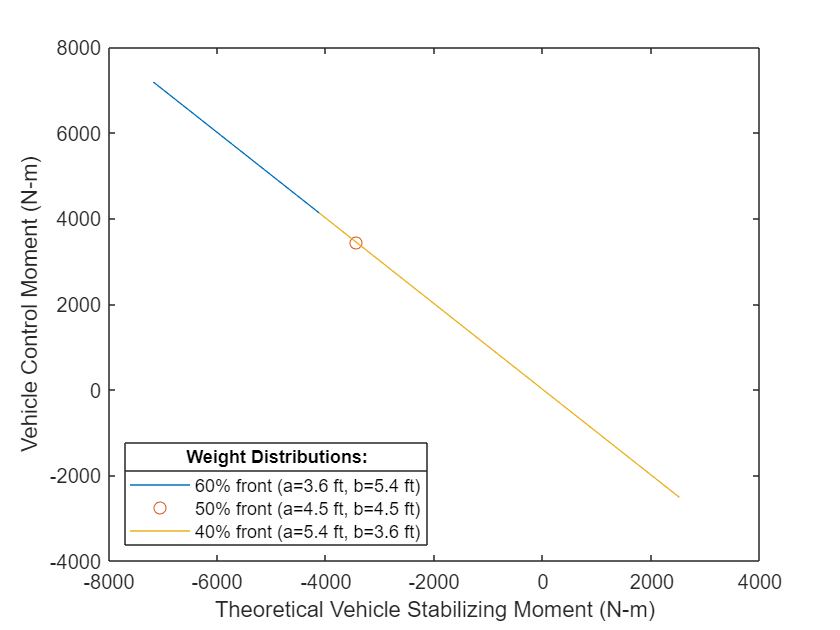

Nd = [];
d = [];
for i=1:length(v_x)
    Nd(:,i) = ones(1,3).*(a*C_alpha_F);
    a_y = v_x(i)^2/R;
    UG = (m*((C_alpha_R*b)-(C_alpha_F*a)))/(l*C_alpha_F*C_alpha_R);
    d_A = l/R;
    d(:,i) = d_A+(UG*a_y);
end
X = (NB.*B)+(Nr.*r);
Y = Nd.*d;
plot(X(1,:),Y(1,:))
hold on;
plot(X(2,:),Y(2,:), 'o')
plot(X(3,:),Y(3,:))
hold off;
xlabel("Theoretical Vehicle Stabilizing Moment (N-m)")
ylabel("Vehicle Control Moment (N-m)")
lgd = legend("60% front (a=3.6 ft, b=5.4 ft)", "50% front (a=4.5 ft, b=4.5 ft)", "40% front (a=5.4 ft, b=3.6 ft)",'Location','SW');
title(lgd,'Weight Distributions:')

### Problem 3

**Vehicle Parameters:**

- Mass: 1637 kg

- Yaw inertia: 3326 kg-m^2

- Wheelbase: 2.736 m

- Weight distribution: 60% to front

- Front cornering stiffness: 802 N/deg

- Rear cornering stiffness: 785 N/deg

- Steering ratio: 15:1 (15 degree at the steering wheel = 1 degree at the front wheel)

**Maneuver Description:**

In this problem, you are required to simulate the bicycle model for the maneuver that is described below. Based on the description, you should create a vector of inputs for the simulation.

The roadwheel steering angle is the input to your bicycle model. In the first maneuver, provide a step input for this steering angle. The vehicle is first being driven down a straight line at 74 mph for 7 seconds after which the driver holds the handwheel position constant at 45 degrees for 60 seconds. The handwheel position is then returned to 0 degrees and the maneuver is terminated

**Answer the following:**

Using a state-space approach, determine the states, $\beta$ and $\dot{\psi}$, of the bicycle model for the complete maneuver. Assume a linear tire model. Provide plots for each maneuver (1) $\beta$ v/s time, (2) $\dot{\psi}$v/s time, (3) $\alpha_f$ v/s time, and (4) $\alpha_r$ vs time for the entire length of the simulation. (Total 4 plots)

### Solution 3

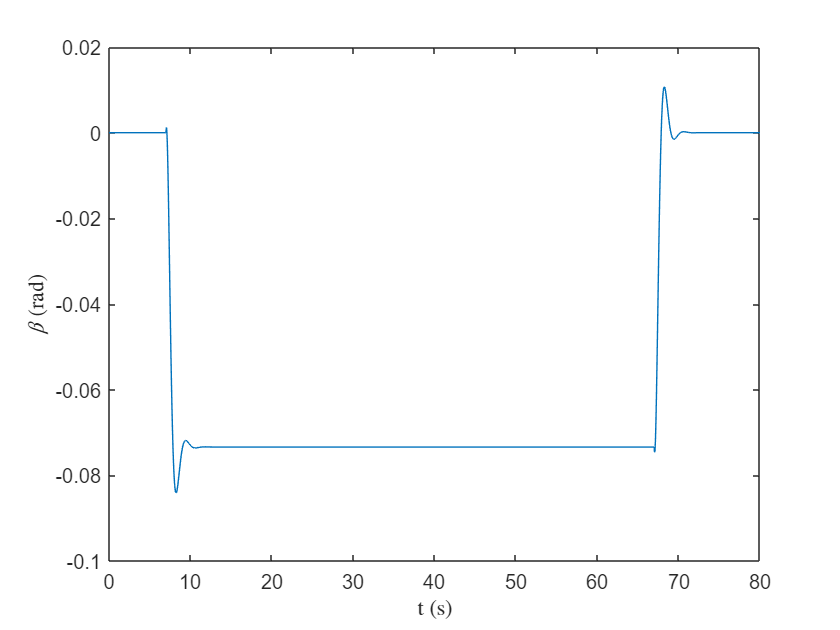

m = 1637; % kg
Iz = 3326; % kg-m^2
l = 2.736; % m
a = 0.4*l;
b = l-a;
C_alpha_F = 802; % N/deg
C_alpha_F = C_alpha_F*(180/pi); % N/rad
C_alpha_R = 785; % N/deg
C_alpha_R = C_alpha_R*(180/pi); % N/rad
SR = 15;
v_x = 74; % mph
v_x = v_x/2.237; % m/s

% Single-Track Model
a11 = -((C_alpha_R+C_alpha_F)/(m*v_x));
a12 = (((C_alpha_R*b)-(C_alpha_F*a))/(m*v_x^2))-1;
a21 = ((C_alpha_R*b)-(C_alpha_F*a))/(Iz);
a22 = -((C_alpha_R*b^2)+(C_alpha_F*a^2))/(Iz*v_x);
b1 = (C_alpha_F)/(m*v_x);
b2 = (C_alpha_F*a)/(Iz);
A = [a11 a12; a21 a22];
B = [b1; b2];

% Initialization
dt = 0.001; % s
X = [];
X(:,1) = [0;0];
X_dot = [];
u = [ones(1,7000)*0 ones(1,60000)*(deg2rad(45)/SR) ones(1,13000)*0]; % steering input (rad) at each millisecond

% Simulation at each millisecond
for t=1:80000
    X_dot(:,t) = A*X(:,t)+B*u(t);
    X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
end
alpha_F = [0 u] - (X(2,:)*a)/v_x - X(1,:);
alpha_R = (X(2,:)*b)/v_x - X(1,:);

% Plot
t = 0:80000; % ms
plot(t/1000,X(1,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\beta$ (rad)",'interpreter','latex')

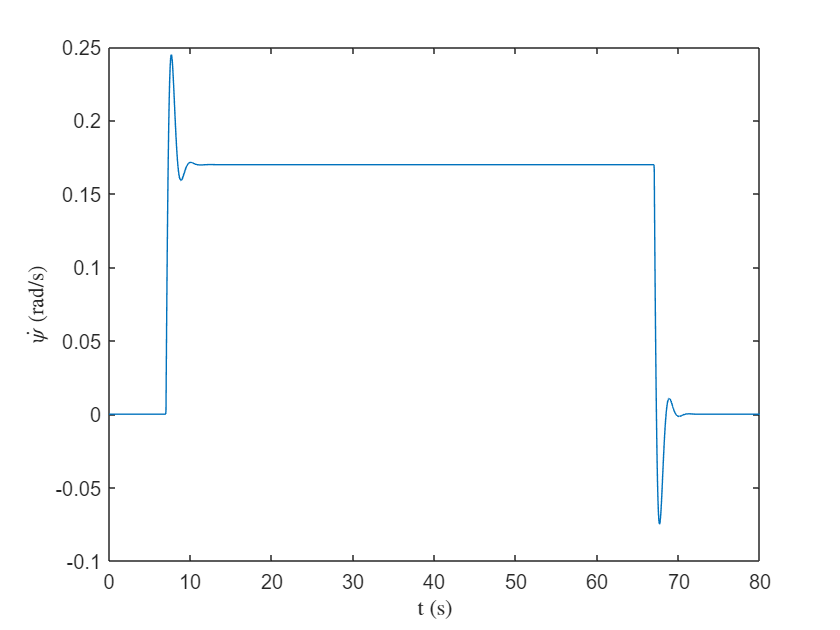

plot(t/1000,X(2,:))
xlabel("t (s)",'interpreter','latex')
ylabel("$\dot{\psi}$ (rad/s)",'interpreter','latex')

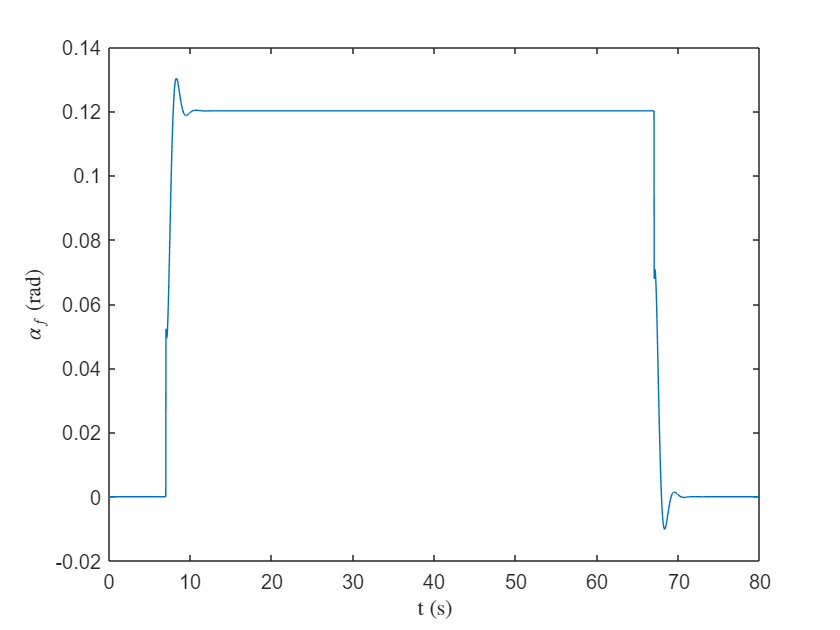

plot(t/1000,alpha_F)
xlabel("t (s)",'interpreter','latex')
ylabel("$\alpha_f$ (rad)",'interpreter','latex')

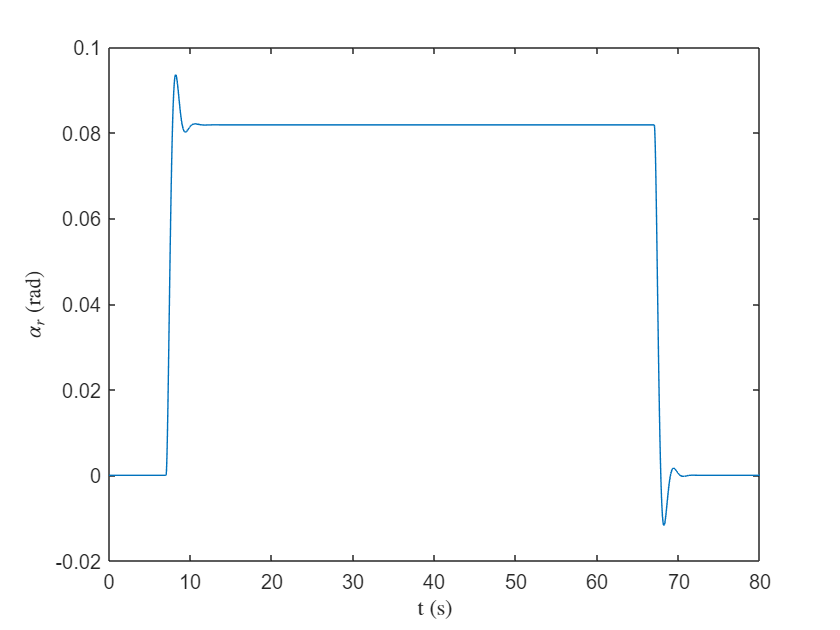

plot(t/1000,alpha_R)
xlabel("t (s)",'interpreter','latex')
ylabel("$\alpha_r$ (rad)",'interpreter','latex')